## Les premiers pas avec MATLAB

[Installation de MATLAB](https://confluence.hefr.ch/display/public/KBExterneHEFR/Installation+de+Matlab)

### Faire des calculs

1+1

ans = 2

2^2

ans = 4

sin(2*pi)

ans = -2.4493e-16

log(exp(1))  % natural logarithm

ans = 1

log10(10^1)  % logarithm to base 10

ans = 1

### Vecteurs et matrices

vec1 = [1 2 3]

vec1 =      1     2     3


vec2 = [3; 2; 1]

vec2 =      3
     2
     1


vec3 = 1:10

vec3 =      1     2     3     4     5     6     7     8     9    10


vec4 = 0:0.1:1

vec4 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000



mat1 = [1 2 3; 4 5 6; 7 8 9]

mat1 =      1     2     3
     4     5     6
     7     8     9



mult = mat1 * vec2

mult =     10
    28
    46


%mult = mat1 * vec1

transpose = mat1'

transpose =      1     4     7
     2     5     8
     3     6     9


%vec1 + vec2
vec1 + vec2'

ans =      4     4     4


vec1 + 1

ans =      2     3     4


vec1 * 2

ans =      2     4     6


vec1.^2

ans =      1     4     9


log(vec1)

ans =          0    0.6931    1.0986


### Créer les graphes

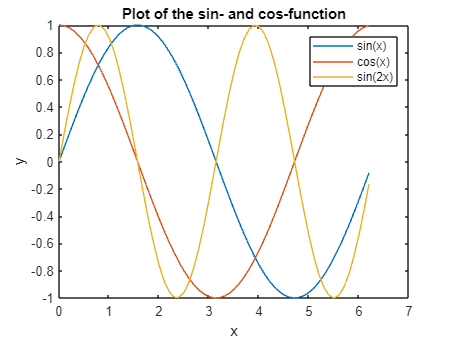

x = 0:0.1:2*pi;
sinx = sin(x);
cosx = cos(x);
plot(x, [sinx; cosx])
hold on
plot(x, sin(2*x))
title('Plot of the sin- and cos-function');
legend('sin(x)', 'cos(x)', 'sin(2x)');
xlabel('x'); ylabel('y');

### Ecrire un texte

Cela est très facile :

- Un peu comme Word, mais pas beaucoup d'options.

- On peut ajouter les formules (Insert -> Equation): $a^2 +b^2 =c^2$ 

- et les liens : [Notre école](http://www.heia-fr.ch)

- et les images

### Utiliser notre bibliothèque de fluides ADVENS

Il faut toujours copier le(s) fichier(s) dans le dossier actuel !!

**Syntaxe :** ADVENS_`Props(outprop, inprop1, invalue1, inprop2, invalue2, fluid)`

- outprop = propriété recherchée

- inprop1, invalue1 = 1ere propriété donnée (propriété + valeur)

- inprop2, invalue2 = 2e propriété donnée (propriété + valeur)

- fluid = nom du fluide

Les propriétés implémentées dans la bibliothèque sont

- input:  `"v"` (volume spécifique), `"P"` (pression), `"T"` (température), `"h"` (enthalpie), `"s"` (entropie), `"x"` (qualité de vapeur), `"u"` (énergie interne)

- output: toutes les propriétés input plus              `"ViscDyn"` (viscosité dynamique), `"ViscCin"` (viscosité cinétique), `"Ro"` (densité), `"ThermCond"` (conductivité thermique), `"Prandtl"` (nombre de Prandtl), `"Cp"` (capacité thermique)

C'est toujours en unités SI !

**Exemples :**

ADVENS_Props("Ro", "P", 101325, "T", 80+273.15, "H2O") % P en pascal, T en K

ans = 971.7904

ADVENS_Props('ThermCond', 'P', 101325, 'T', 50+273.15, 'H2O')

ans = 0.6406

ADVENS_Props("T", "P", 101325, "x", 0.1, "H2O")

ans = 373.1243

%ADVENS_Props("T", "h", 1000, "x", 0.1, "H2O")

ADVENS_Props("Ro", "P", 101325, "T", 80+273.15, "R134a")

ans = 3.5617